**This script prepares metadata for further analysis.**

The most important is adding correct promis data from OLP4CBP repo (final_12mo & healthies_measure) to the metadata provided in the brainpathway object with preprocesses fMRI data.

today = datestr(datetime("today"),'yymmdd'); % for saving files at the end

% load metadata from the brainpathway object
load("Data/raw/brainpathway_data_gsr_censoring_pipeline_nosmoothing.mat")

Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


metadata = bs.subject_metadata;

% load correct promis data
meta_w_correct_promis = readtable("Data/raw/final_12mo_outcomes_wide.csv");
cols_CBP = {'pain_avg_t1_arm_1', 'bpi_intensity_t1_arm_1', 'bpi_interference_t1_arm_1', 'odi_t1_arm_1', 'promis_dep_t1_arm_1', 'promis_anger_t1_arm_1', 'promis_anxiety_t1_arm_1', 'promis_sleep_t1_arm_1'};
final_CBP = meta_w_correct_promis(:, cols_CBP);
final_CBP.id = meta_w_correct_promis.id; % add id column
% remove arm from column names
final_CBP.Properties.VariableNames = regexprep(final_CBP.Properties.VariableNames,"_arm_1","");

% load correct healthies measures
load("Data/raw/healthies_measures.mat")
% add 9000 to HC ids -> this is how they are coded in the brainpathway metadata
healthies_measures.id = healthies_measures.id + 9000

healthies_measures = 55×17 table
     id     pain_avg    panas_pa    panas_na    bpi_intensity    bpi_interference    odi    pcs    promis_dep    promis_anger    promis_anxiety    promis_sleep    tsk11    sopa_emo    alcohol    opioid    cannabis
    ____    ________    ________    ________    _____________    ________________    ___    ___    __________    ____________    ______________    ____________    _____    ________    _______    ______

final_HC = healthies_measures(:, regexprep(cols_CBP,"_t1_arm_1",""));
% add t1 to column names
final_HC.Properties.VariableNames = append(final_HC.Properties.VariableNames, "_t1");
final_HC.id = healthies_measures.id; % add id column

% join promis data from CBP & HC vertically
final_promis_all = [final_CBP; final_HC]  % 197 rows

final_promis_all = 198×9 table
    pain_avg_t1    bpi_intensity_t1    bpi_interference_t1    odi_t1    promis_dep_t1    promis_anger_t1    promis_anxiety_t1    promis_sleep_t1    id 
    ___________    ________________    ___________________    ______    _____________    _______________    _________________    _______________    ___

         3                2.5                 1.5714            10           17                 9                  17                  30            23
         4                4.5                 3.1429            18           12                16                  15                  21            24
         4                  4                 1.4286  


% check final_promis index against brainpathway metadata indices
setdiff(final_promis_all.id, metadata.id)  % in final promis but not in brainpathway: 9013, 9017, 9033, 9052

ans =         9013
        9017
        9033
        9052


setdiff(metadata.id, final_promis_all.id) % in brainpathway but not in final promis: 12, 14, 15, 18, 29, 32, 38, 69, 1004

ans =           12
          14
          15
          18
          29
          32
          38
          69
        1004


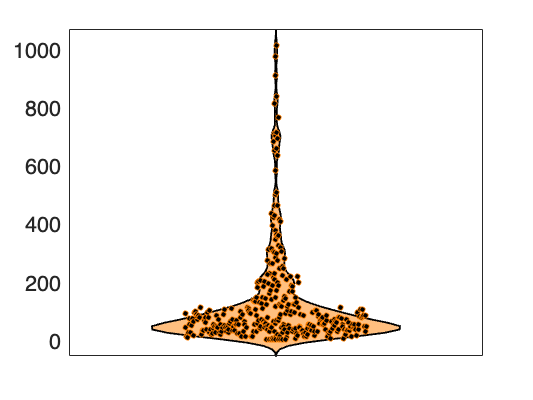

% merge correct CBP promis cols with all metadata
merged = outerjoin(metadata, final_promis_all, 'Keys', 'id', 'Type','Left', 'MergeKeys',true);
merged.negative_affect_t1 = mean(merged{:, {'promis_dep_t1', 'promis_anger_t1', 'promis_anxiety_t1'}}, 2);

% remove old bs_meta columns
merged = removevars(merged, regexprep(cols_CBP,"_t1_arm_1",""));


% add column with motion outliers (>3std above the HC mean)
HC_motion_std = std(rmmissing(merged(merged.is_patient == 0,:).n_spike_regs_sponpain));

HC_motion_std = 66.2184

merged.motion_outliers = merged.n_spike_regs_sponpain > HC_motion_std*3;


ans = 3×3 table
           is_patient    time    GroupCount
           __________    ____    __________

    0_1      false        1          49    
    1_1      true         1         120    
    1_2      true         2         109    


% li = [{'is_patient', 'motion_outliers'}, regexprep(cols_CBP,"_arm_1","")]
% grpstats(merged(merged.time==1, li), {'is_patient', 'motion_outliers'}, 'median')

ans = 3×3 table
           is_patient    time    GroupCount
           __________    ____    __________

    0_1      false        1          51    
    1_1      true         1         151    
    1_2      true         2         135    


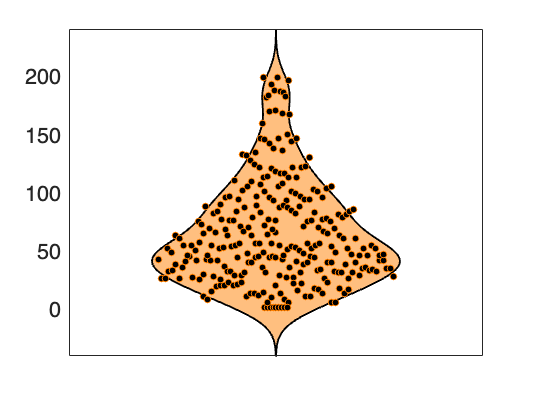

% figure
% vs = violinplot(test.n_spike_regs_sponpain, test.is_patient);


writetable(merged, ['Data/', today '_metadata_prepped.csv']);